### **Digital Signal Processing / AVE** 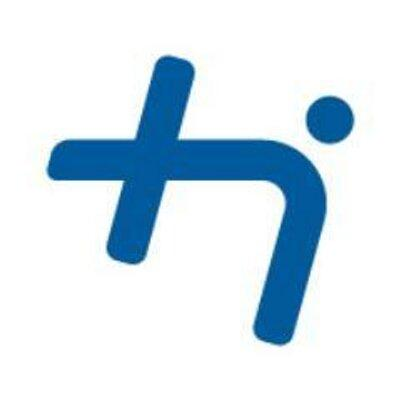

#### **Prof. Dr. Michael Mecking**

# **Analysis of LTI-Systems**

The **z-Transform** of a signal $x[n]$ is given by the relationship


$$X(z) = \sum_{n=-\infty}^{\infty} x[n] \, z^{-n}.$$


For a system described by a linear constant coefficient difference equation (CCDE)


$$\sum_{k=0}^{N} a_k y[n-k] = \sum_{m=0}^{M} b_m x[n-m], \quad \text{with} \ a_0=1$$


the **system function** $H(z)$ as z-Transform of the impulse repsonse $h[n]$ is given by

$H(z) = \frac{\sum_{k=0}^M b_k \, z^{-k}}{\sum_{k=0}^N a_k \, z^{-k}}
			    = b_0 \, \frac{\prod_{k=1}^M (1-c_k \, z^{-1})}{\prod_{k=1}^N (1-d_k \, z^{-1}) }$.

The $M$ zeroes of the transfer function $H(z)$ are located at $c_k, \, k = 1, \ldots, M$ and the $N$ poles of the transfer function are located at $d_k, \, k = 1, \ldots, N$. 

For a system to be stable and causal, all poles $d_k$ need to be located inside the unit circle, and the region of convergence of $H(z)$ is outside the outermost pole.

## System 1

### Problem 1.1

Consider the **System 1** given by the rational system function


$$H_1(z) = \frac{1}{6}\, \frac{(1-0.98\,e^{j0.8\pi} z^{-1})(1-0.98\,e^{-j0.8\pi} z^{-1}) } {(1-0.8\,e^{j0.4\pi} z^{-1})(1-0.8\,e^{-j0.4\pi}z^{-1}) }.$$


You may find the coefficients $\{a_k\}$and $\{b_m\}$ of the CCDE describing this system based on the poles and zeroes of the system (or transfer) function $H(z)$ using MATLAB's command *zp2tf (zero-pole to transfer function, *check documentation in MATLAB*).*

Find the coefficients $\{b_m\}$ of the numerator polynomial and the coefficients $\{a_k\}$ of the denominator polynomial of the given system function $H_1(z)$.

% pole / zeroes to system/transfer function
% your code...

z1 = 0.98 * exp(1j * 0.8 * pi);
z2 = 0.98 * exp((-1j) * 0.8 * pi);
p1 = 0.8 * exp(1j * 0.4 * pi);
p2 = 0.8 * exp((-1j) * 0.4 * pi);

z1 = [z1; z2];
p1 = [p1; p2];
k = 1 / 6; %gain

[b1, a1] = zp2tf(z1, p1, k);

disp('Numarator:')

Numarator:


disp(b1);

    0.1667    0.2643    0.1601




disp('Denominator:')

Denominator:


disp(a1);

    1.0000   -0.4944    0.6400



### Problem 1.2

Plot the location of the zeores and poles of the system function $H_1(z)$ using MATLAB's command *zplane *(once again, check documentation).

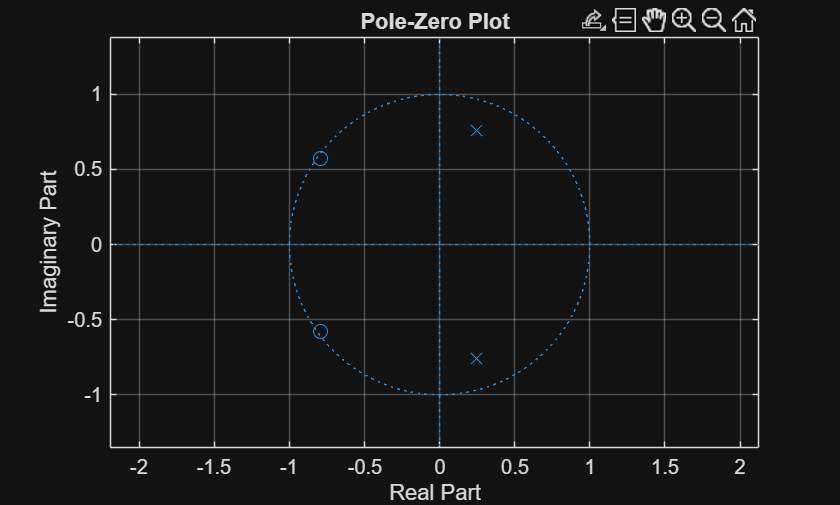

% plot the zeroes and poles of H1(z)
figure
% your code...
zplane(z1, p1);
grid on

### **Problem 1.3**

Plot and observe the magnitude response $|H_1(e^{j\Omega})|$ and phase response $\arg H_1(e^{j\Omega})$ of System 1.

Would you describe System 1 as having a constant magnitude response or linear phase?

Can you correlate the location of zeroes and poles to the magnitude as well as phase response?

How does the magnitude response change near a pole or a zero?

How does the phase response change near a pole or a zero?

Try to understand the following (simple) computation of the frequency response using MATLAB's build-in commands!

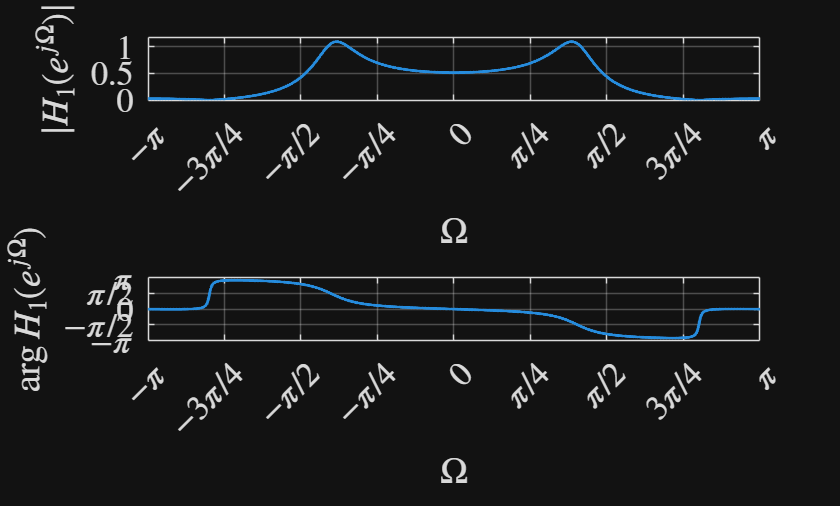

% evaluate the magnitude and phase response of system 1 
% given by coefficient vectors b1 and a1

numf = 2048;
H1   = freqz(b1, a1, numf, 'whole');  % freqz evaluates the frequency response at numf 
                                      % frequencies equally spaced on the
                                      % unit circle,
                                      % however, starting at z = 1 = e^{j0}!

H1    = circshift(H1, numf/2);        % we need to circularly shift by half the samples in order to have the 
                                      % frequencies ranging from (-pi, pi).

Omega = linspace(-pi*(1-1/numf), pi, numf);

% plot the magnitude and phase response
figure
subplot(2,1,1)
plot(Omega, abs(H1), 'LineWidth',1.5)
axis([-pi pi 0 1.1*max(abs(H1))])
xticks([-pi -3/4*pi -pi/2 -pi/4 0 pi/4 pi/2 3*pi/4 pi])
xticklabels({'$-\pi$','$-3\pi/4$','$-\pi/2$', '$-\pi/4$', '$0$', '$\pi/4$', '$\pi/2$', '$3\pi/4$', '$\pi$'})
set(gca,'TickLabelInterpreter', 'latex')
grid
set(gca,'FontSize', 17)
xlabel("$\Omega$", Interpreter="latex")
ylabel("$|H_1(e^{j\Omega})|$", Interpreter="latex")

subplot(2,1,2)
plot(Omega, angle(H1), 'LineWidth',1.5)
axis([-pi pi -pi pi])
xticks([-pi -3/4*pi -pi/2 -pi/4 0 pi/4 pi/2 3*pi/4 pi])
xticklabels({'$-\pi$','$-3\pi/4$','$-\pi/2$', '$-\pi/4$', '$0$', '$\pi/4$', '$\pi/2$', '$3\pi/4$', '$\pi$'})
yticks([-pi -pi/2 0 pi/2 pi])
yticklabels({'$-\pi$','$-\pi/2$', '$0$', '$\pi/2$', '$\pi$'})
set(gca,'TickLabelInterpreter', 'latex')
grid
set(gca,'FontSize', 17)
xlabel("$\Omega$", Interpreter="latex")
ylabel("$\arg H_1(e^{j\Omega})$", Interpreter="latex")

**Observations:**

- constant magnitude response or linear phase : No, distinct peaks and dips and also phase response is nonlinear

- Phase changes faster near both poles and zeros

- Near poles : Magnitude increase sharply and higher slop

- Near zeros : magnitude decrease and and higher dip

## System 2

### Problem 2.1

The system function of **System 2** has 8 zeroes and poles. The poles are at locations


$$d_k = 0.95 \, e^{j(0.15\pi+0.02\pi \cdot k)}, \quad k = 1, 2, 3, 4$$


and additionally at the complex-conjugate locations


$$d_{k} = d_{k-4} ^{*}, \quad k = 5,6,7,8.$$


The zeroes are at the complex-conjugate reciprocal locations of the poles, i.e.,


$$c_k = 1/d_k^{*}, \quad 1 \le k \le 8.$$


Plot the pole and zero locations of the system function $H_2(z)$.

% pole / zeroes of system 2
figure
% your code...
dk = 0.95 * exp((1j * ((0.15 * pi) + (0.02 * pi * (1:4)))));
dk_conj = conj(dk);
dk = [dk, dk_conj]

dk =    0.8177 + 0.4836i   0.7857 + 0.5340i   0.7506 + 0.5823i   0.7126 + 0.6282i   0.8177 - 0.4836i   0.7857 - 0.5340i   0.7506 - 0.5823i   0.7126 - 0.6282i


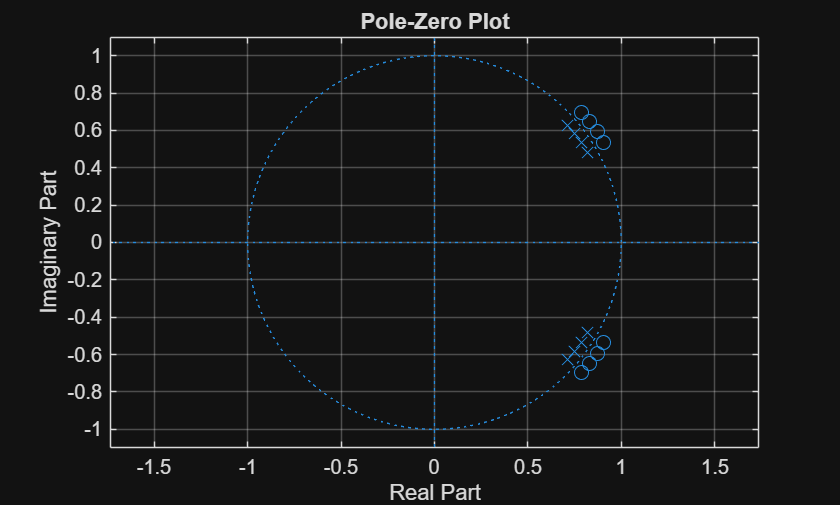

ck = 1./ dk;

zplane(ck', dk');
grid on

### **Problem 2.2**

Plot the magnitude and phase response of System 2. The magnitude response of System 2 is to be normalised so that $H_2(e^{j0}) = 1$.

What do you observe looking at the magnitude and phase response of System 2 (taking into account the pole/zero locations)?

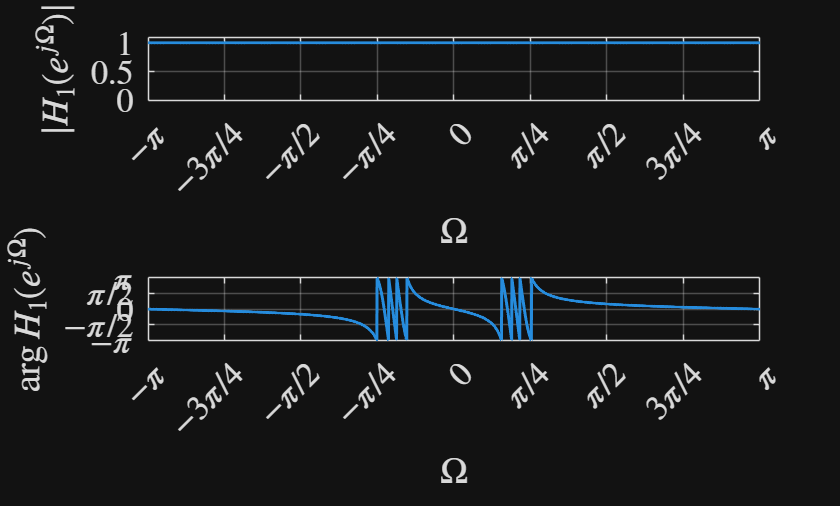

% your code...

[b2, a2] = zp2tf(ck', dk', k);

numf = 2048;
H1   = freqz(b2, a2, numf, 'whole');  % freqz evaluates the frequency response at numf 
                                      % frequencies equally spaced on the
                                      % unit circle,
                                      % however, starting at z = 1 = e^{j0}!

H1    = circshift(H1, numf/2);        % we need to circularly shift by half the samples in order to have the 
                                      % frequencies ranging from (-pi, pi).

Omega = linspace(-pi*(1-1/numf), pi, numf);

H1 = H1 * sum(a2) / sum(b2) ; % To normalize

% plot the magnitude and phase response
figure
subplot(2,1,1)
plot(Omega, abs(H1), 'LineWidth',1.5)
axis([-pi pi 0 1.1*max(abs(H1))])
xticks([-pi -3/4*pi -pi/2 -pi/4 0 pi/4 pi/2 3*pi/4 pi])
xticklabels({'$-\pi$','$-3\pi/4$','$-\pi/2$', '$-\pi/4$', '$0$', '$\pi/4$', '$\pi/2$', '$3\pi/4$', '$\pi$'})
set(gca,'TickLabelInterpreter', 'latex')
grid
set(gca,'FontSize', 17)
xlabel("$\Omega$", Interpreter="latex")
ylabel("$|H_1(e^{j\Omega})|$", Interpreter="latex")

subplot(2,1,2)
plot(Omega, angle(H1), 'LineWidth',1.5)
axis([-pi pi -pi pi])
xticks([-pi -3/4*pi -pi/2 -pi/4 0 pi/4 pi/2 3*pi/4 pi])
xticklabels({'$-\pi$','$-3\pi/4$','$-\pi/2$', '$-\pi/4$', '$0$', '$\pi/4$', '$\pi/2$', '$3\pi/4$', '$\pi$'})
yticks([-pi -pi/2 0 pi/2 pi])
yticklabels({'$-\pi$','$-\pi/2$', '$0$', '$\pi/2$', '$\pi$'})
set(gca,'TickLabelInterpreter', 'latex')
grid
set(gca,'FontSize', 17)
xlabel("$\Omega$", Interpreter="latex")
ylabel("$\arg H_1(e^{j\Omega})$", Interpreter="latex")

**Observations:**

- Magnitude response : Normalized so linear

- phase response: nonlinear variation with rapid transitions near the pole/zero angles. 

## Concatenating System 1 and System 2

The following signal $x[n]$ is to be processed by a serial concatenation of Systems 1 and System 2. The signal $x[n]$ comprised three sine-signals


$$x_1[n] = w[n] \cdot \cos(0.2\pi n)$$



$$x_2[n] = w[n] \cdot \cos(0.4\pi n - \pi/2)$$



$$x_3[n] = w[n] \cdot \cos(0.8\pi n + \pi/5)$$


with the window-signal $w[n]$ given by the so called Hamming-window


$$w[n] = 0.54 - 0.46 \cos \left( \frac{2\pi \, n}{M} \right), \quad 0 \le n \le M, \quad M = 60.$$


The input signal $x[n]$ is then evaluated as the superposition of the three sine-signals with appropriate delays


$$x[n] = x_3[n] + x_1[n-M-1] + x_2[n-2M-2].$$


### Problem 3.1

Plot the signal $x[n]$ (we use MATLAB's *plot* command (not *stem*, this time - mind that the signal is nevertheless discrete-time!) as well as the magnitude $|X(e^{j\Omega})|$ of the DTFT of $x[n]$.

Can you discern the three pulses of different frequencies in the time- as well as frequency-domain? 

Note that the blurring of the discrete cosine-frequencies in the frequency domain is due to the multiplication with the window $w[n]$ corresponding to a convolution in the frequency domain!

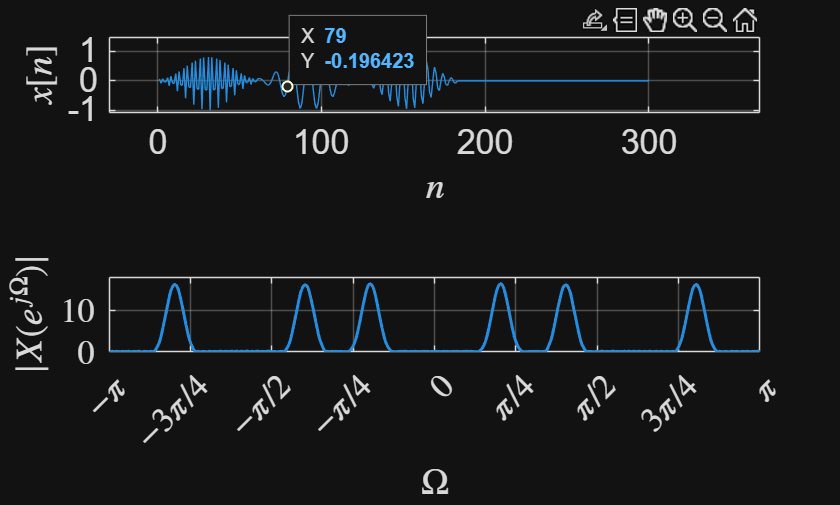

% Nothing is to be done here - except run the code :-)

% generation of the signal x[n]
n  = 0:1:60;
w  = hamming(61);
x1 = w' .* cos(0.2*pi*n);
x2 = w' .* cos(0.4*pi*n - pi/2);
x3 = w' .* cos(0.8*pi*n + pi/5);

x = [x3 x1 x2 zeros(1,117)]; % zeros appended to make signal length = 300 samples

% plot of x[n] and magnitude of frequency response of x[n]
figure
subplot(2,1,1)
plot(x)
grid
axis([1 300 -1 1])
set(gca,'FontSize', 17)
xlabel("$n$", Interpreter="latex")
ylabel("$x[n]$", Interpreter="latex")

% frequency response of the signal x
numf = 512;
X = fft(x, numf);
X = circshift(X, numf/2);
Omega = linspace(-pi*(1-1/numf), pi, numf);

% plot magnitude response
subplot(2,1,2)
plot(Omega, abs(X), 'LineWidth',1.5)

axis([-pi pi 0 1.1*max(abs(X))])
xticks([-pi -3/4*pi -pi/2 -pi/4 0 pi/4 pi/2 3*pi/4 pi])
xticklabels({'$-\pi$','$-3\pi/4$','$-\pi/2$', '$-\pi/4$', '$0$', '$\pi/4$', '$\pi/2$', '$3\pi/4$', '$\pi$'})
set(gca,'TickLabelInterpreter', 'latex')
grid
set(gca,'FontSize', 17)
xlabel("$\Omega$", Interpreter="latex")
ylabel("$|X(e^{j\Omega})|$", Interpreter="latex")

### **Problem 3.2**

Process the signal $x[n]$ by the cascade of System1 and twice(!) System 2.

MATLAB's command *filter* might come in handy - check the usage using MATLAB's documentation.

Plot the output signal $y_1[n]$ of System 1 and the output signal $y_2[n]$ after the cascade with (two-times!) System 2. 

Comment on the results! 

What do you observe after the signal was processed by system 1, and how do you explain the changes in the signal imposed by system 2?

% filter the signal x[n] by systems 1 and 2
% your code...
y0 = filter(b1, a1, x)

y0 =     0.0108    0.0087   -0.0019   -0.0057   -0.0045    0.0057    0.0021   -0.0019    0.0013   -0.0053    0.0048   -0.0001   -0.0026    0.0044   -0.0062    0.0047   -0.0006   -0.0031    0.0055   -0.0062    0.0042   -0.0004   -0.0030    0.0049   -0.0049    0.0029    0.0000   -0.0023    0.0032   -0.0026    0.0011    0.0004   -0.0011    0.0008    0.0000   -0.0007    0.0007    0.0002   -0.0015    0.0024   -0.0022    0.0008    0.0013   -0.0031    0.0038   -0.0028    0.0006    0.0019   -0.0037    0.0038


y2 = filter(b2, a2, y0)

y2 =     0.0018    0.0003   -0.0013   -0.0001    0.0013    0.0026   -0.0000   -0.0012    0.0000   -0.0008    0.0018   -0.0001   -0.0007    0.0006   -0.0019    0.0010   -0.0006   -0.0005    0.0016   -0.0012    0.0015   -0.0003   -0.0007    0.0011   -0.0013    0.0009   -0.0001   -0.0004    0.0007   -0.0009    0.0002   -0.0001   -0.0002    0.0004    0.0002    0.0001    0.0003   -0.0001   -0.0005    0.0003   -0.0008    0.0002    0.0003   -0.0006    0.0010   -0.0007    0.0003    0.0003   -0.0008    0.0010


y22 = filter(b2, a2, y2)

y22 =     0.0003   -0.0002   -0.0003    0.0002    0.0004    0.0003   -0.0004   -0.0002    0.0003    0.0001    0.0005   -0.0002   -0.0002    0.0002   -0.0003    0.0004   -0.0001   -0.0001    0.0002   -0.0005    0.0003   -0.0002   -0.0000    0.0004   -0.0002    0.0003   -0.0001   -0.0001    0.0002   -0.0002    0.0001    0.0000   -0.0001    0.0000   -0.0001   -0.0001    0.0000    0.0000    0.0000    0.0002   -0.0001    0.0001   -0.0000   -0.0002    0.0002   -0.0002    0.0001    0.0001   -0.0002    0.0002


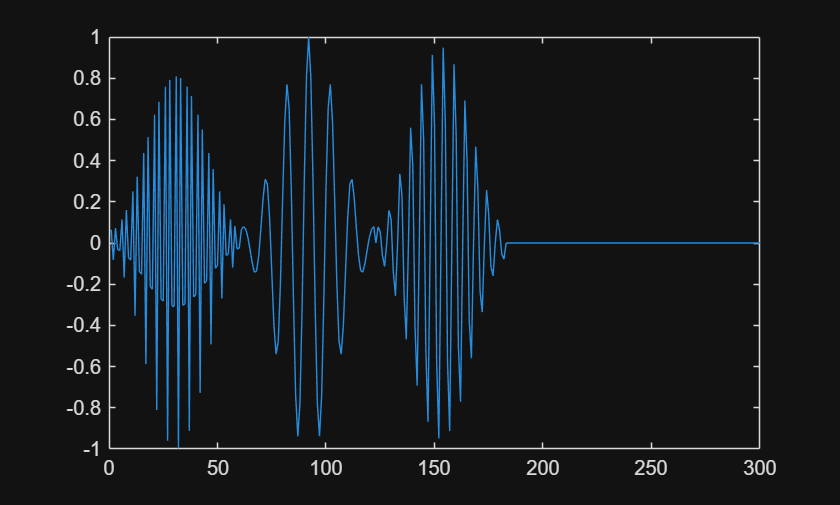

figure
plot(x) 

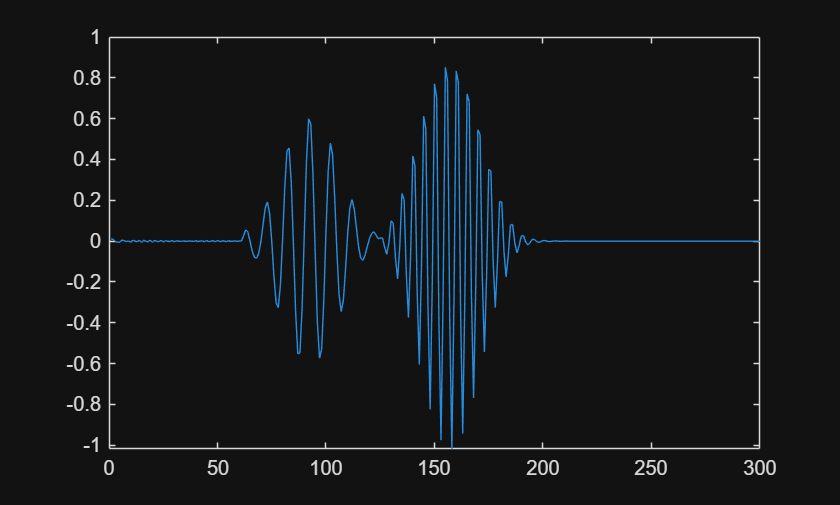

plot(y0)

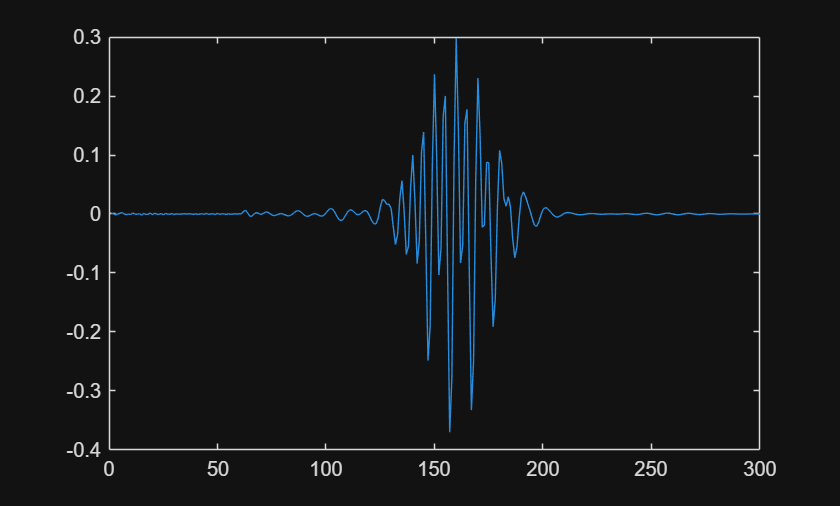

plot(y2)

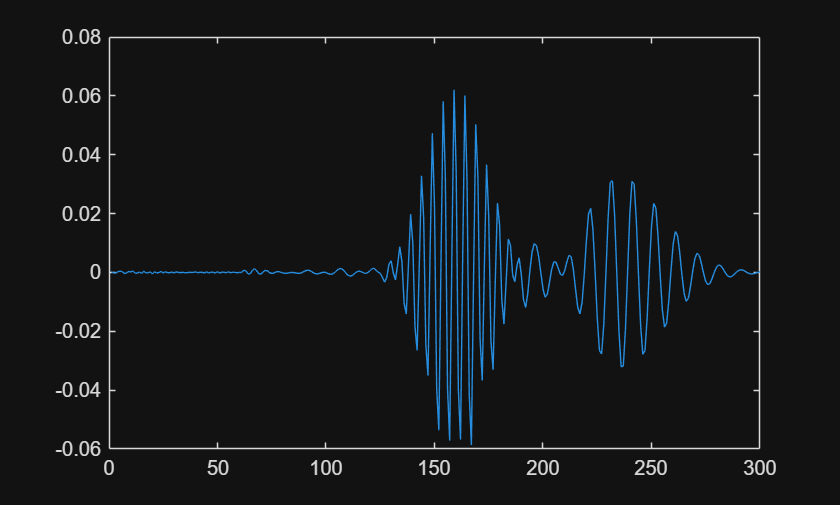

plot(y22)